% a04_p1_pr_debugging

% This script sets ExpInfo.nTrials = 20 and counts = 100 to debug, i.e., test if
% fitted parameters are the same as true parameters. Also plots true
% parameters against real parameters
 
clear all; close all; clc; rng(1); parpool(2);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).



%% initiate confusion matrix

nModel = 5;
CM = zeros(nModel);
counts = 100;

%% experimental parameters

ExpInfo.ifi              = 1000/60;
ExpInfo.SOA              = [-0.5000, -0.3000, -0.2500, -0.2000, -0.1500, -0.1000,...
    -0.0500, 0, 0.0500, 0.1000, 0.1500, 0.2000, 0.2500, 0.3000, 0.5000]*1000; % in ms
ExpInfo.lenS             = length(ExpInfo.SOA);
ExpInfo.nTrials          = 20; % num of trials per SOA

%% ground truth parameters

% used the ground truth parameters from sub7 sess 7 SOA = -300 ms
TruePara                 = {[40, -20, 70, 50, 110, 80, 0.01, 0.06], ...%M1
    [40, -20, 70, 110, 80, 0.01, 0.06], ...%M2
    [40, -20, 70, 50, 110, 0.01, 0.06], ...%M3
    [40, -20, 70, 110, 0.01, 0.06], ...%M4
    [40, 70, 110, 0.01, 0.06]};%M5

ParaLabel = {{'\mu_{pre}','\mu_{post}','\sigma_{pre}','\sigma_{post}','criterion_{pre}','criterion_{post}','\lambda_{pre}','\lambda_{post}'},...
    {'\mu_{pre}','\mu_{post}','\sigma','criterion_{pre}','criterion_{post}','\lambda_{pre}','\lambda_{post}'},...
    {'\mu_{pre}','\mu_{post}','\sigma_{pre}','\sigma_{post}','criterion','\lambda_{pre}','\lambda_{post}'},...
    {'\mu_{pre}','\mu_{post}','\sigma','criterion','\lambda_{pre}','\lambda_{post}'},...
    {'\mu','\sigma','criterion','\lambda_{pre}','\lambda_{post}'}};

%% functions

% define PMF
P_Afirst                 = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig);
P_Vfirst                 = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig));
P_simultaneous           = @(SOA, mu, sig, c, lambda) ...
    1 - (lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig)) ...
    - (lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig)));

M1                       = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(3), p(5), p(7));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(3), p(5), p(7));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(3), p(5), p(7));...
    @(p) P_Vfirst(ExpInfo.SOA, p(2), p(4), p(6), p(8));...
    @(p) P_simultaneous(ExpInfo.SOA, p(2), p(4), p(6), p(8));...
    @(p) P_Afirst(ExpInfo.SOA, p(2), p(4), p(6), p(8))};

M2                       = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(3), p(4), p(6));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(3), p(4), p(6));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(3), p(4), p(6));...
    @(p) P_Vfirst(ExpInfo.SOA, p(2), p(3), p(5), p(7));...
    @(p) P_simultaneous(ExpInfo.SOA, p(2), p(3), p(5), p(7));...
    @(p) P_Afirst(ExpInfo.SOA, p(2), p(3), p(5), p(7))};

M3                       = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(3), p(5), p(6));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(3), p(5), p(6));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(3), p(5), p(6));...
    @(p) P_Vfirst(ExpInfo.SOA, p(2), p(4), p(5), p(7));...
    @(p) P_simultaneous(ExpInfo.SOA, p(2), p(4), p(5), p(7));...
    @(p) P_Afirst(ExpInfo.SOA, p(2), p(4), p(5), p(7))};

M4                       = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(3), p(4), p(5));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(3), p(4), p(5));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(3), p(4), p(5));...
    @(p) P_Vfirst(ExpInfo.SOA, p(2), p(3), p(4), p(6));...
    @(p) P_simultaneous(ExpInfo.SOA, p(2), p(3), p(4), p(6));...
    @(p) P_Afirst(ExpInfo.SOA, p(2), p(3), p(4), p(6))};

M5                       = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(2), p(3), p(4));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(2), p(3), p(4));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(2), p(3), p(4));...
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(2), p(3), p(5));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(2), p(3), p(5));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(2), p(3), p(5))};

models                   = {M1; M2; M3; M4; M5};

%% run model fitting for multiple times

% initialization
[deltaAIC, estP] = deal(cell(counts, nModel));

for count = 1:counts
    count

    %% simulate fake datasets for 5 models
    for iModel                   = 1:nModel

        % for the specific model and its corresponding ground-truth
        % parameter sets, generate the probability of reporting: Vfirst,
        % simultaneous, Afirst in pretest; Vfirst, simultaneous, Afirst in
        % posttest
        p_all_cond               = NaN(6, ExpInfo.lenS); % len of conditions x len of SOA levels
        Para                     = TruePara{iModel}; % true parameters for this model
        for iCondition           = 1:6
            p_all_cond(iCondition,:) = models{iModel}{iCondition}(Para);
        end

        % simulate data set
        sim_r_org                = cell(1,2);
        for s                    = 1:2 % loop through pre and post session
            p                        = p_all_cond(((s-1)*3+1):s*3, :); % pre and post probability of reporting V,simul, A
            sim_r_org{s}             = sampleMatrix(p, ExpInfo.nTrials);
        end

        %% fit fake data to 5 models 

        % obtain best-fitting parameters and AIC for each model
        [deltaAIC{count, iModel}, estP{count, iModel}]  = para_comp_fitting_fake_data_v2(sim_r_org, ExpInfo, iModel);

        % iBest is the index of model that best fits this specific fake data set
        [M iBEST] = min(deltaAIC{count, iModel});
        BEST = deltaAIC{count, iModel} == M;
        BEST = BEST / sum(BEST);
        CM(iModel,:) = CM(iModel,:) + BEST;

    end
end

count = 1

count = 2

count = 3

count = 4

count = 5

count = 6

count = 7

count = 8

count = 9

count = 10

count = 11

count = 12

count = 13

count = 14

count = 15

count = 16

count = 17

count = 18

count = 19

count = 20

count = 21

count = 22

count = 23

count = 24

count = 25

count = 26

count = 27

count = 28

count = 29

count = 30

count = 31

count = 32

count = 33

count = 34

count = 35

count = 36

count = 37

count = 38

count = 39

count = 40

count = 41

count = 42

count = 43

count = 44

count = 45

count = 46

count = 47

count = 48

count = 49

count = 50

count = 51

count = 52

count = 53

count = 54

count = 55

count = 56

count = 57

count = 58

count = 59

count = 60

count = 61

count = 62

count = 63

count = 64

count = 65

count = 66

count = 67

count = 68

count = 69

count = 70

count = 71

count = 72

count = 73

count = 74

count = 75

count = 76

count = 77

count = 78

count = 79

count = 80

count = 81

count = 82

count = 83

count = 84

count = 85

count = 86

count = 87

count = 88

count = 89

count = 90

count = 91

count = 92

count = 93

count = 94

count = 95

count = 96

count = 97

count = 98

count = 99

count = 100

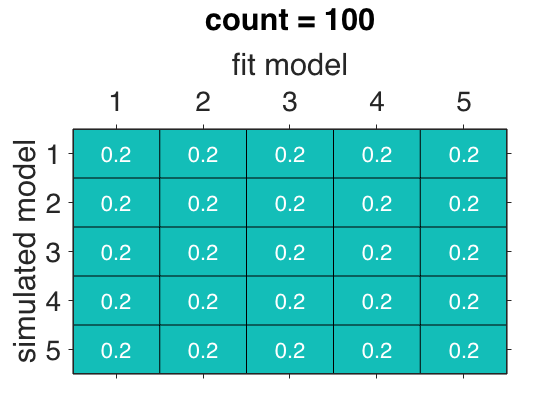

%% summary plot of CM

figure(1); clf;
FM = round(100*CM/sum(CM(1,:)))/100;
t = imageTextMatrix(FM);
set(t(FM'<0.3), 'color', 'w')
hold on;
[l1, l2] = addFacetLines(CM);
set(t, 'fontsize', 22)
title(['count = ' num2str(count)]);
set(gca, 'xtick', [1:5], 'ytick', [1:5], 'fontsize', 28, ...
    'xaxislocation', 'top', 'tickdir', 'out')
xlabel('fit model')
ylabel('simulated model')

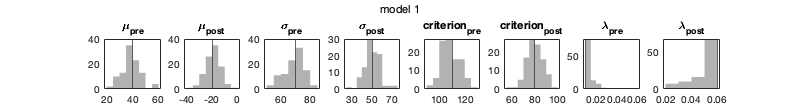

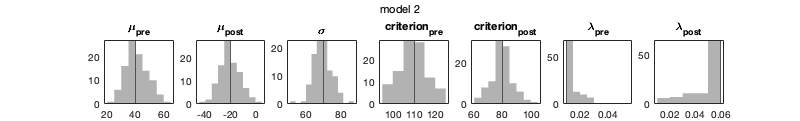

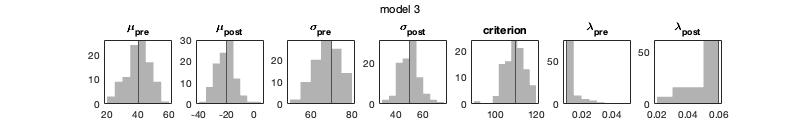

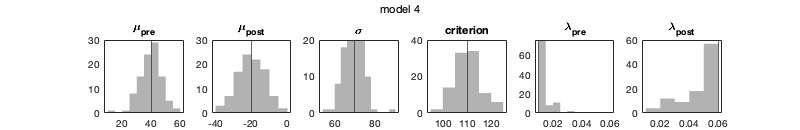

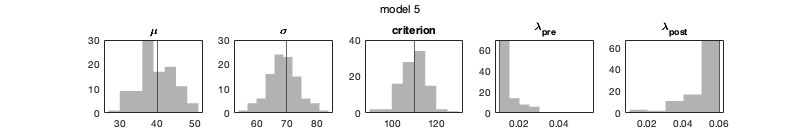


%% summary plot of true and fitted parameters

for m            = 1:5 % for each model
    true_para = TruePara {m};
    n_para = length(true_para);
    fit_para = NaN(size(true_para));
    for c = 1:counts
        fit_para(c,:) = cell2mat(estP{c,m}); %c: trial of fits; first m: generating model; second m: fitted model
    end
    figure; clf; hold on % create a figure for each model
    set(gcf, 'Position', [0,0,200*n_para,130])
    sgtitle(['model ' num2str(m)])
    for p = 1:n_para % create subplot for each parameter
        subplot(1,n_para,p)
        histogram(fit_para(:,p),'EdgeAlpha',0,'FaceColor','k','FaceAlpha',0.3);
        xline(true_para(p))
        title(ParaLabel{m}{p})
    end
    saveas(gcf, ['pr_model' num2str(m)],'epsc')
end

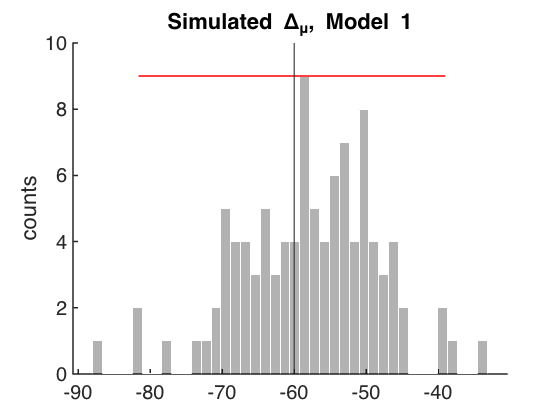


% for the full model, plot simulated mu_diff 

for m            = 1:1 % for the full model
    true_para = TruePara {m};
    n_para = length(true_para);
    fit_para = NaN(size(true_para));
    for c = 1:counts
        fit_para(c,:) = cell2mat(estP{c,m}); %c: trial of fits; first m: generating model; second m: fitted model
    end
end

% calcualte mu_diff for each simulation
mu_diff = fit_para(:,2) - fit_para(:,1);
true_mu_diff = true_para(2) - true_para (1);

% calculate 95% CI
[lb, ub] = get95CI(mu_diff);

% plot histogram of mu_diff
figure; hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
histogram(mu_diff,40,'EdgeColor','w','FaceColor','k','FaceAlpha',0.3);
xline(true_mu_diff,'LineWidth',1.5) % true mu difference

% plot 95% CI
yl = ylim;
hCI = yl(2)*0.9;
plot([lb ub],[hCI hCI],'r-','LineWidth',1.5)

% look better
ylabel('counts')
title('Simulated \Delta_{\mu}, Model 1')

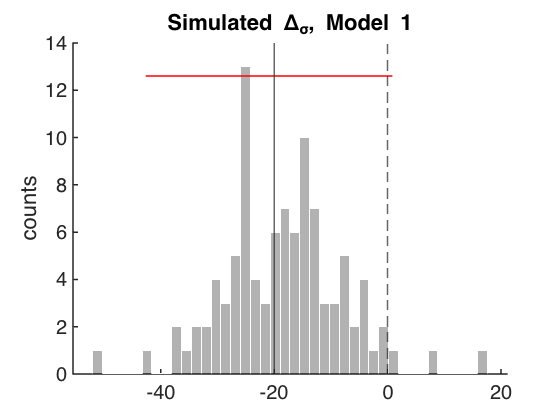

% for the full model, plot simulated sigma_diff

for m            = 1:1 % for the full model
    true_para = TruePara {m};
    n_para = length(true_para);
    fit_para = NaN(size(true_para));
    for c = 1:counts
        fit_para(c,:) = cell2mat(estP{c,m}); %c: trial of fits; first m: generating model; second m: fitted model
    end
end

% calcualte mu_diff for each simulation
sigma_diff = fit_para(:,4) - fit_para(:,3);
true_sigma_diff = true_para(4) - true_para (3);

% calculate 95% CI
[lb, ub] = get95CI(sigma_diff);

% plot histogram of sigma_diff
figure; hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
histogram(sigma_diff,40,'EdgeColor','w','FaceColor','k','FaceAlpha',0.3);
xline(true_sigma_diff,'LineWidth',1.5) % true mu difference
xline(0,'--','LineWidth',1.5) % zero

% plot 95% CI
yl = ylim;
hCI = yl(2)*0.9;
plot([lb ub],[hCI hCI],'r-','LineWidth',1.5)


% look better
ylabel('counts')
title('Simulated \Delta_{\sigma}, Model 1')